# Machine Learning Online Class

## Initialization

clear ; close all; clc

## =========== Part 1: Loading and Visualizing Data =============

% Load Training Data
fprintf('Loading and Visualizing Data ...\n')

Loading and Visualizing Data ...


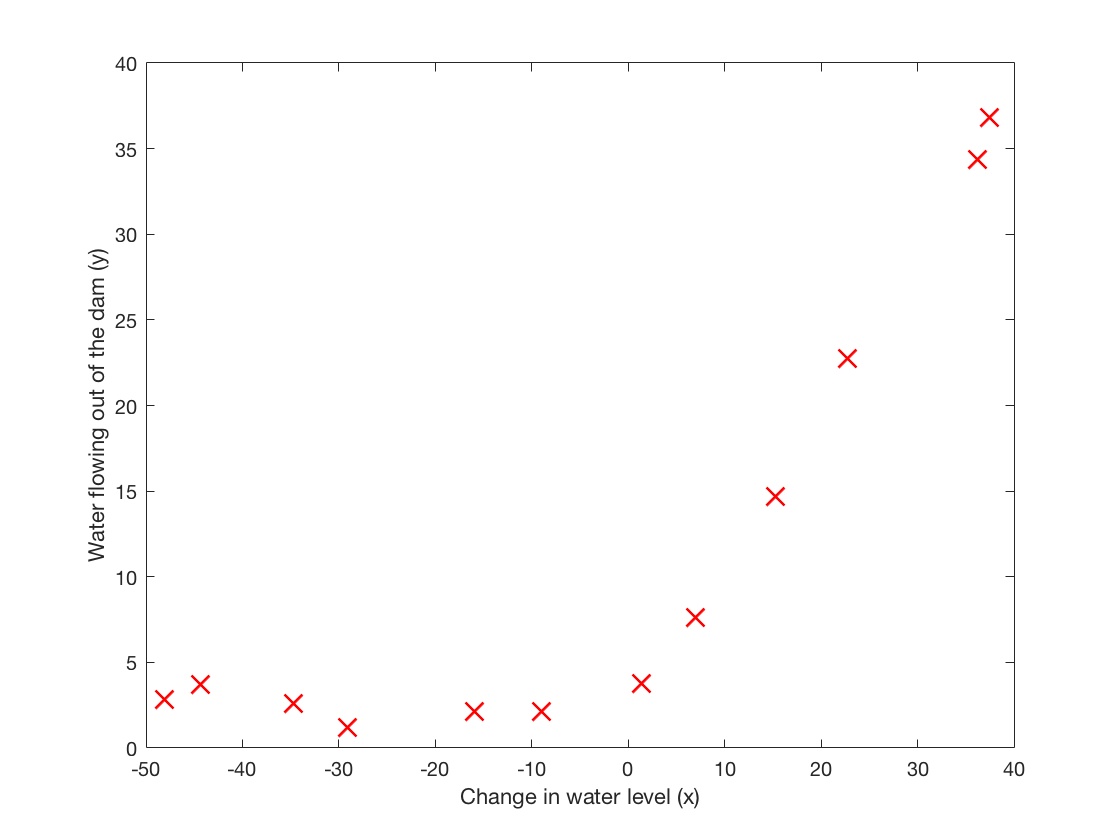


% Load from ex5data1: 
% You will have X, y, Xval, yval, Xtest, ytest in your environment
load ('ex5data1.mat');

% m = Number of examples
m = size(X, 1);

% Plot training data
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');


fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## =========== Part 2: Regularized Linear Regression Cost =============

theta = [1 ; 1];
J = linearRegCostFunction([ones(m, 1) X], y, theta, 1);

fprintf(['Cost at theta = [1 ; 1]: %f '...
         '\n(this value should be about 303.993192)\n'], J);

Cost at theta = [1 ; 1]: 303.993192 
(this value should be about 303.993192)



fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## =========== Part 3: Regularized Linear Regression Gradient =============

theta = [1 ; 1];
[J, grad] = linearRegCostFunction([ones(m, 1) X], y, theta, 1);

fprintf(['Gradient at theta = [1 ; 1]:  [%f; %f] '...
         '\n(this value should be about [-15.303016; 598.250744])\n'], ...
         grad(1), grad(2));

Gradient at theta = [1 ; 1]:  [-15.303016; 598.250744] 
(this value should be about [-15.303016; 598.250744])



fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## =========== Part 4: Train Linear Regression =============

%  Train linear regression with lambda = 0
lambda = 0;
[theta] = trainLinearReg([ones(m, 1) X], y, lambda);

Iteration     1 | Cost: 1.052435e+02
Iteration     2 | Cost: 2.237391e+01


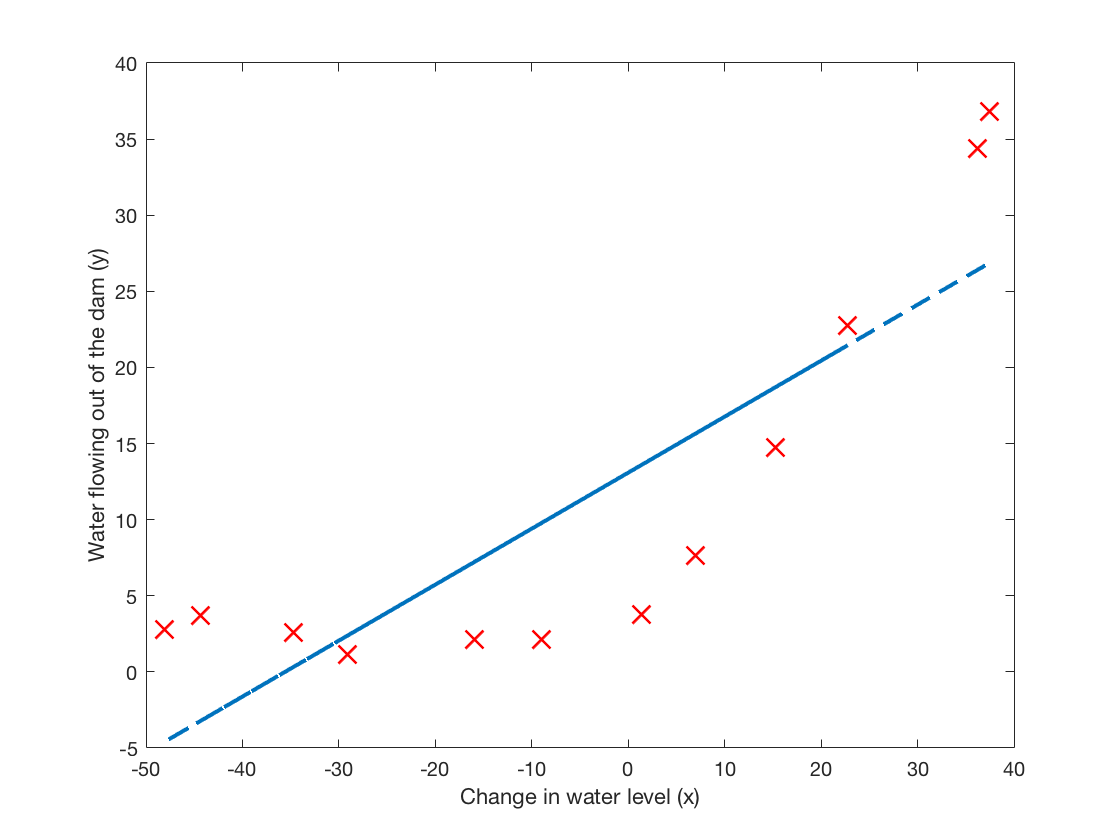


%  Plot fit over the data
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
hold on;
plot(X, [ones(m, 1) X]*theta, '--', 'LineWidth', 2)

hold off;


fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## =========== Part 5: Learning Curve for Linear Regression =============

lambda = 0;
[error_train, error_val] = ...
    learningCurve([ones(m, 1) X], y, ...
                  [ones(size(Xval, 1), 1) Xval], yval, ...
                  lambda);

Iteration     1 | Cost: 2.663868e-01
Iteration     2 | Cost: 3.944305e-31
Iteration     3 | Cost: 0.000000e+00
Iteration     1 | Cost: 4.282328e-01
Iteration     2 | Cost: 8.295365e-30
Iteration     3 | Cost: 4.930381e-32
Iteration     1 | Cost: 1.021540e+02
Iteration     2 | Cost: 3.286595e+00
Iteration     4 | Cost: 3.286595e+00
Iteration     5 | Cost: 3.286595e+00
Iteration     1 | Cost: 1.438726e+02
Iteration     2 | Cost: 1.035224e+02
Iteration     3 | Cost: 7.536716e+01
Iteration     4 | Cost: 1.615422e+01
Iteration     5 | Cost: 3.619255e+00
Iteration     6 | Cost: 2.843147e+00
Iteration     7 | Cost: 2.842791e+00
Iteration     8 | Cost: 2.842765e+00
Iteration     9 | Cost: 2.842679e+00
Iteration    10 | Cost: 2.842679e+00
Iteration    11 | Cost: 2.842679e+00
Iteration    12 | Cost: 2.842678e+00
Iteration    13 | Cost: 2.842678e+00
Iteration    14 | Cost: 2.842678e+00
Iteration    15 | Cost: 2.842678e+00
Iteration    16 | Cost: 2.842678e+00
Iteration    17 | Cost: 2.842678e+00
I

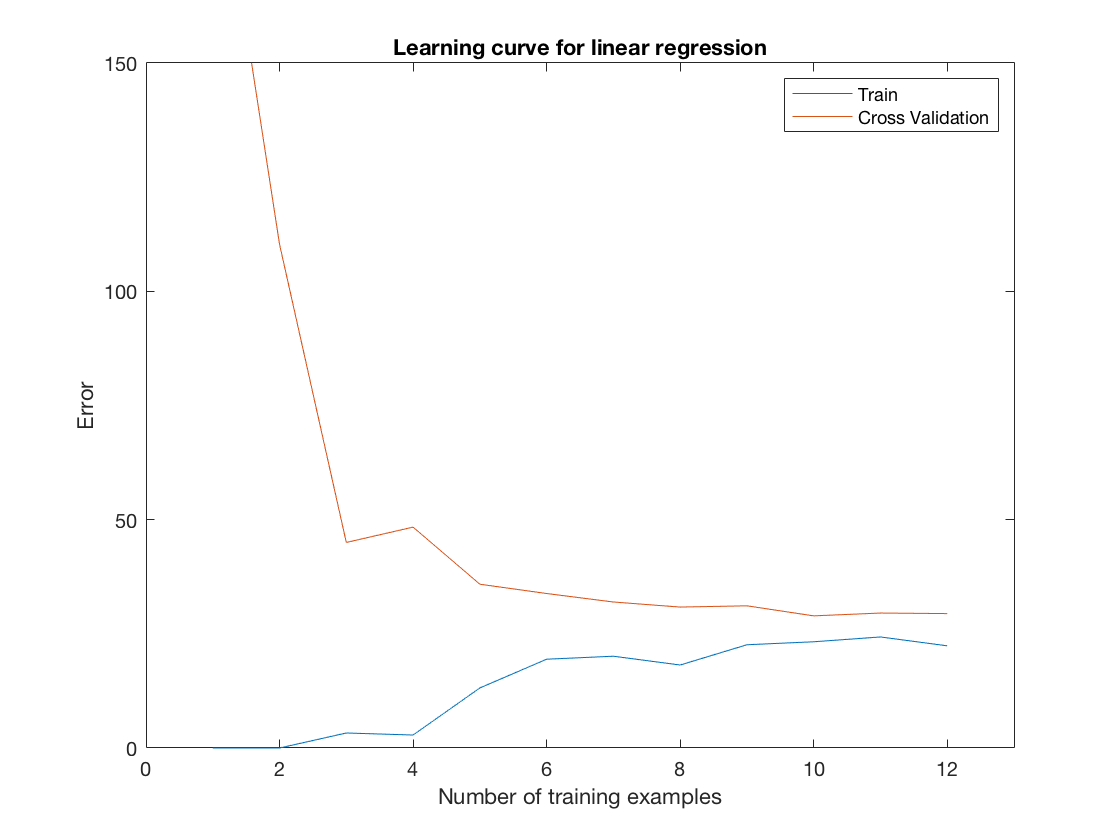


plot(1:m, error_train, 1:m, error_val);
title('Learning curve for linear regression')
legend('Train', 'Cross Validation')
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 150])


fprintf('# Training Examples\tTrain Error\tCross Validation Error\n');

# Training Examples	Train Error	Cross Validation Error


for i = 1:m
    fprintf('  \t%d\t\t%f\t%f\n', i, error_train(i), error_val(i));
end

  	1		0.000000	205.121096
  	2		0.000000	110.300366
  	3		3.286595	45.010231
  	4		2.842678	48.368911
  	5		13.154049	35.865165
  	6		19.443963	33.829962
  	7		20.098522	31.970986
  	8		18.172859	30.862446
  	9		22.609405	31.135998
  	10		23.261462	28.936207
  	11		24.317250	29.551432
  	12		22.373906	29.433818



fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## =========== Part 6: Feature Mapping for Polynomial Regression =============

p = 8;

% Map X onto Polynomial Features and Normalize
X_poly = polyFeatures(X, p);
[X_poly, mu, sigma] = featureNormalize(X_poly);  % Normalize
X_poly = [ones(m, 1), X_poly];                   % Add Ones

% Map X_poly_test and normalize (using mu and sigma)
X_poly_test = polyFeatures(Xtest, p);
X_poly_test = bsxfun(@minus, X_poly_test, mu);
X_poly_test = bsxfun(@rdivide, X_poly_test, sigma);
X_poly_test = [ones(size(X_poly_test, 1), 1), X_poly_test];         % Add Ones

% Map X_poly_val and normalize (using mu and sigma)
X_poly_val = polyFeatures(Xval, p);
X_poly_val = bsxfun(@minus, X_poly_val, mu);
X_poly_val = bsxfun(@rdivide, X_poly_val, sigma);
X_poly_val = [ones(size(X_poly_val, 1), 1), X_poly_val];           % Add Ones

fprintf('Normalized Training Example 1:\n');

Normalized Training Example 1:


fprintf('  %f  \n', X_poly(1, :));

  1.000000  
  NaN  
  NaN  
  NaN  
  NaN  
  NaN  
  NaN  
  NaN  
  NaN  



fprintf('\nProgram paused. Press enter to continue.\n');


Program paused. Press enter to continue.


pause;

## =========== Part 7: Learning Curve for Polynomial Regression =============

lambda = 0;
[theta] = trainLinearReg(X_poly, y, lambda);

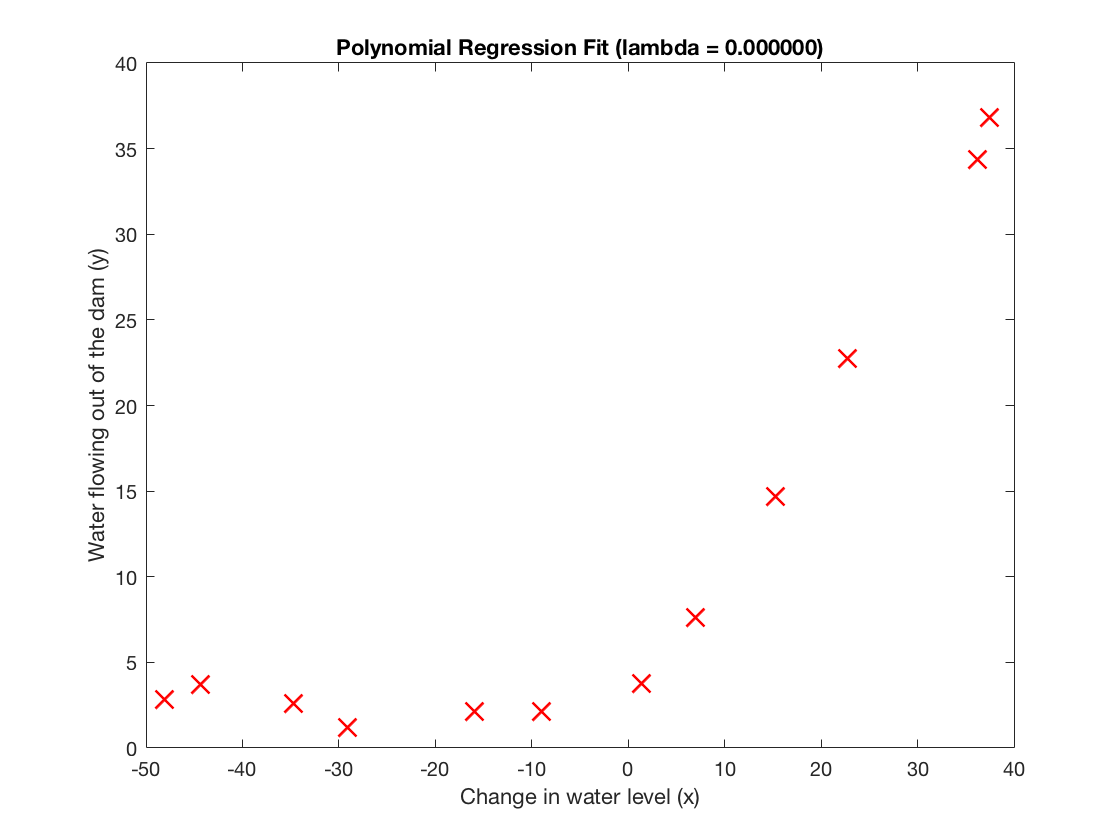


% Plot training data and fit
figure(1);
plot(X, y, 'rx', 'MarkerSize', 10, 'LineWidth', 1.5);
plotFit(min(X), max(X), mu, sigma, theta, p);
xlabel('Change in water level (x)');
ylabel('Water flowing out of the dam (y)');
title (sprintf('Polynomial Regression Fit (lambda = %f)', lambda));


figure(2);
[error_train, error_val] = ...
    learningCurve(X_poly, y, X_poly_val, yval, lambda);

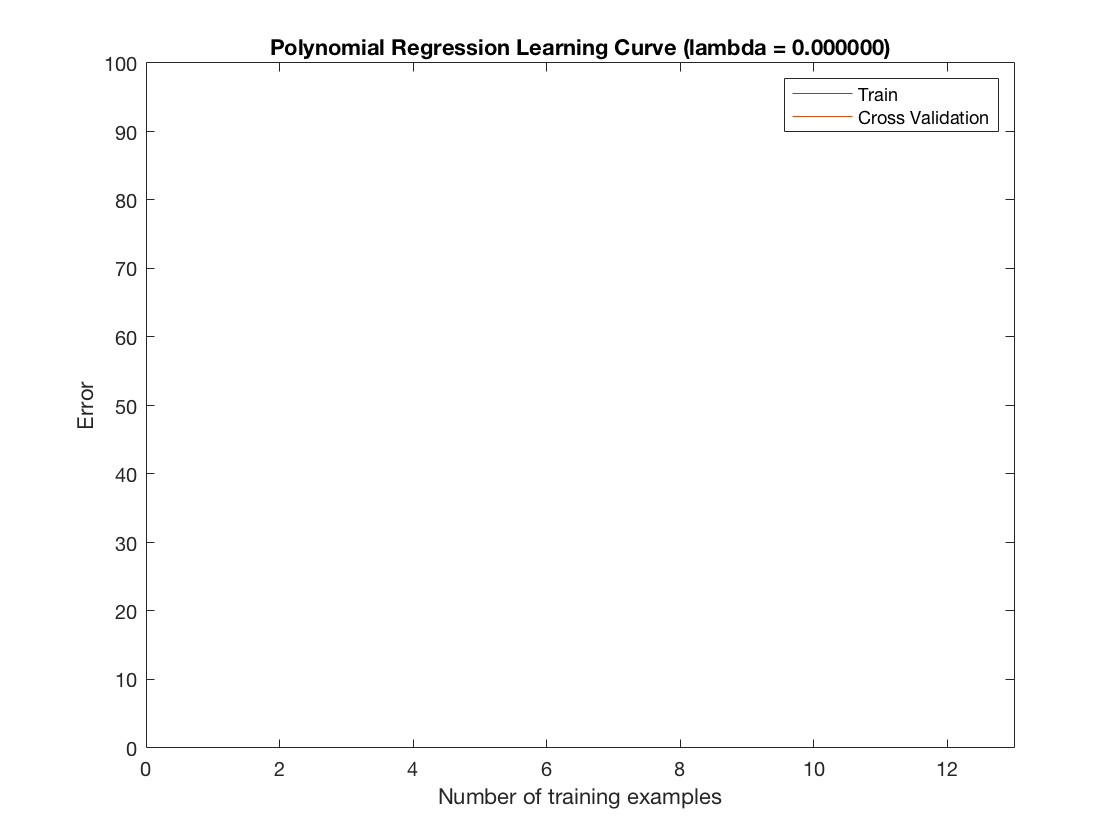

plot(1:m, error_train, 1:m, error_val);

title(sprintf('Polynomial Regression Learning Curve (lambda = %f)', lambda));
xlabel('Number of training examples')
ylabel('Error')
axis([0 13 0 100])
legend('Train', 'Cross Validation')


fprintf('Polynomial Regression (lambda = %f)\n\n', lambda);

Polynomial Regression (lambda = 0.000000)



fprintf('# Training Examples\tTrain Error\tCross Validation Error\n');

# Training Examples	Train Error	Cross Validation Error


for i = 1:m
    fprintf('  \t%d\t\t%f\t%f\n', i, error_train(i), error_val(i));
end

  	1		NaN	NaN
  	2		NaN	NaN
  	3		NaN	NaN
  	4		NaN	NaN
  	5		NaN	NaN
  	6		NaN	NaN
  	7		NaN	NaN
  	8		NaN	NaN
  	9		NaN	NaN
  	10		NaN	NaN
  	11		NaN	NaN
  	12		NaN	NaN



fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## =========== Part 8: Validation for Selecting Lambda =============

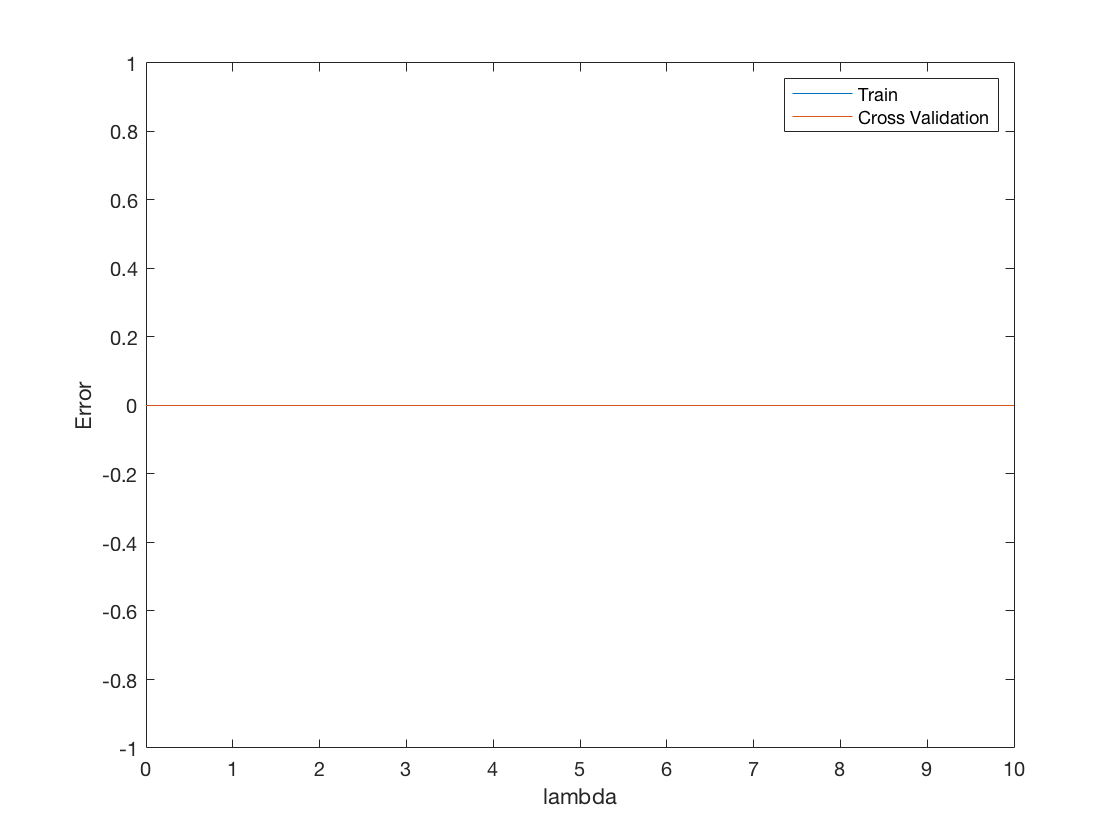

[lambda_vec, error_train, error_val] = ...
    validationCurve(X_poly, y, X_poly_val, yval);

close all;
plot(lambda_vec, error_train, lambda_vec, error_val);
legend('Train', 'Cross Validation');
xlabel('lambda');
ylabel('Error');


fprintf('lambda\t\tTrain Error\tValidation Error\n');

lambda		Train Error	Validation Error


for i = 1:length(lambda_vec)
	fprintf(' %f\t%f\t%f\n', ...
            lambda_vec(i), error_train(i), error_val(i));
end

 0.000000	0.000000	0.000000
 0.001000	0.000000	0.000000
 0.003000	0.000000	0.000000
 0.010000	0.000000	0.000000
 0.030000	0.000000	0.000000
 0.100000	0.000000	0.000000
 0.300000	0.000000	0.000000
 1.000000	0.000000	0.000000
 3.000000	0.000000	0.000000
 10.000000	0.000000	0.000000



fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;